clearvars
%Ignore the codes below
% =========================================================================
% DEFINE KWAVEARRAY
% =========================================================================

% create empty array
% karray = kWaveArray
% % define arc properties
% radius    = 30e-3;              % [mm]
% diameter  = 30e-3;              % [mm]
% focus_pos = [-2.5e-3, 0];        % [mm]
% 
% % add arc shaped element
% elem_pos  = [-37.5e-3, 0];    % [m]
% karray.addArcElement(elem_pos, radius, diameter, focus_pos);


% move the array down 10 mm, and rotate by 10 degrees (this moves all the
% elements together)
%karray.setArrayPosition([10e-3, 0], 10);




% %define the grid
% Nx = 80;%600
% Ny = 80;%450
% dx = 1e-3;%2e-4
% dy = 1e-3;%2e-4
% Kgrid = kWaveGrid(Nx,dx,Ny,dy);
% c = 1500;
% alpha = 0.75%alpha absorption coefficient
% 
% 
% %define the medium prperty
% medium.sound_speed = 1500;
% medium.alpha_coeff = 0.75;
% medium.alpha_power = 1.5;
% 
% % create the time array explicitly
% Kgrid.t_array = 0:1e-8:8e-5;
% %Kgrid.makeTime(medium.sound_speed,0.3,8e-5);%128SQRT2/1500
% t_array_new = Kgrid.t_array(1:101)
% 
% % assign binary mask from karray to the source mask
% source.p_mask = karray.getArrayBinaryMask(Kgrid)
% 
% % define a time varying sinusoidal source
% source_freq = 1e6;   % [Hz]
% source_mag = 3;         % [Pa]
% %source_signal = source_mag * sin(2 * pi * source_freq * t_array_new);
% source_signal = 1
% % get distributed source signals (this automatically returns a weighted
% % source signal for each grid point that forms part of the source)
% source.p = karray.getDistributedSourceSignal(Kgrid, source_signal);
% 
% % define a single source point
% % source.p_mask = zeros(Nx, Ny);
% % source.p_mask(Nx/2, Ny/2) = 1;
% 
% 
% %% 
% 
% % filter the source to remove high frequencies not supported by the grid
% % source.p = filterTimeSeries(Kgrid, medium, source.p);
% 
% %define the sensor in a line
% x_offset = 2 % [grid points]
% width = 60% [grid points]
% sensor.mask = zeros(Nx, Ny);
% sensor.mask(x_offset, Ny/2 - width/2:1:Ny/2 + width/2) = 1

% run the simulation
%kspaceFirstOrder2D(Kgrid, medium, source, []);
% sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);



% create pml mask (default size in 2D is 20 grid points)
% pml_size = 20;
% pml_mask = false(Nx, Ny);
% pml_mask(1:pml_size, :) = 1;
% pml_mask(:, 1:pml_size) = 1;
% pml_mask(end - pml_size + 1:end, :) = 1;
% pml_mask(:, end - pml_size + 1:end) = 1;
% 
% % plot source and pml masks
% figure;
% imagesc(Kgrid.y_vec, Kgrid.x_vec, source.p_mask | pml_mask);
% axis image;
% colormap(flipud(gray));
% 
% % overlay the physical source positions
% hold on;
% karray.plotArray(false);

clearvars
%define the grid
Nx = 600;%600
Ny = 450;%450
dx = 2e-4;%2e-4
dy = 2e-4;%2e-4
Kgrid = kWaveGrid(Nx,dx,Ny,dy);
c = 1500;
%Kgrid.setTime

%Use point per wavelength ppl to reduce dx until stable
%dx = 2e-4 ppl = 37500
ppw = 40000;
wavelength = 1.5/120*Nx;
dx_new = wavelength/ppw
w = 1500/1e6%1.5mm
p = wavelength/dx

%define the medium prperty
medium.sound_speed = 1500;
medium.alpha_coeff = 0.75;
medium.alpha_power = 1.5;

% create the time array
Kgrid.makeTime(medium.sound_speed,0.3,5e-5);%128SQRT2/1500
t_array_new = Kgrid.t_array(1:126)

% define a single source point
source.p_mask = zeros(Nx, Ny);
source.p_mask(70/120*Nx, Ny/2) = 1;
% source.p_mask(70/120*Nx+50, Ny/2+50) = 1;
% source.p_mask(70/120*Nx+50, Ny/2-50) = 1;
% source.p_mask(70/120*Nx-50, Ny/2+50) = 1;
% source.p_mask(70/120*Nx-50, Ny/2-50) = 1;

% define a time varying sinusoidal source
source_freq = 1e6;   % [Hz]
source_mag = 3;         % [Pa]
source.p = source_mag * sin(2 * pi * source_freq * t_array_new);
%% 

% filter the source to remove high frequencies not supported by the grid
source.p = filterTimeSeries(Kgrid, medium, source.p);

%define the sensor in a line
x_offset = 20/120*Nx % [grid points]
width = 50/90*Ny% [grid points]
sensor.mask = zeros(Nx, Ny);
sensor.mask(x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2) = 1;

% run the simulation
sensor_data = kspaceFirstOrder2D(Kgrid, medium, source, sensor);
% VISUALISATION
% =========================================================================

% plot the initial pressure and sensor distribution
%positive max around 0.043-0.0449
figure;
%imagesc(Kgrid.y_vec * 1e3, Kgrid.x_vec * 1e3, source.p0 + cart2grid(Kgrid, sensor.mask), [-1, 1]);
imagesc(source.p_mask + sensor.mask, [-1, 1]);
%imagesc(source.p0 + sensor.mask, [-1, 1]);
colormap(getColorMap);
ylabel('x-position');
xlabel('y-position');
axis image;
%% 




% plot the simulated sensor data
figure;
[t_sc, scale, prefix] = scaleSI(max(t_array_new));

subplot(2, 1, 1);
plot(source.p)
%plot(t_array_new * scale, source.p, 'k-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([-inf,inf,-inf,inf]);
title('Input Pressure Signal');

subplot(2, 1, 2);
plot(Kgrid.t_array * scale, sensor_data(32,:), 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Signal Amplitude');
axis ([0,100,-0.05,0.05]);
%axis tight;
%axis([0,10.5,-inf,inf]);



%plot all the 32 original sensor signal 
figure
for i = 1:32
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data(i,:), 'r-');

    %axis([0,10.5,-inf,inf]);
    set(gca,'XTick',[],'YTick',[]);
    if i == 1
            %xlabel(['Time [' prefix 's]']);
            ylabel('Signal Amplitude');
            title('Sensor Pressure Signal');
    end
    if i == 32 
        xlabel(['Time [' prefix 's]']);
        %ylabel('Signal Amplitude');
        %title('Sensor Pressure Signal');
    end

end
%% dt=40ns tend=100.04us timestep = 2502 totalt=1e-4




tic
%obtian all the sensor position
sensorpoistion = zeros(1,32);

sensorpoistion =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


j=1;
for i = 1:450
    if sensor.mask(100,i)==1
        
        sensorpoistion(j) = i;
        j = j+1;
    end
end
%sensorpoistion()
%distance from sensor to source mm
distance_map = zeros(1,32);
intensitymap = zeros(1,1600);
%sourceposition =[70/120*Nx, Ny/2]%x=350,y=225
distance = zeros(1,32);
for i = 1:32
    distance(i) = sqrt((sensorpoistion(i)-225)^2+(350-100)^2);
end

%all the source position

%Create a 20mm times 20mm grid, which is 200 times 200
%x from 
map_length = zeros(1,200);
map_width = zeros(1,200);
%x_offset, Ny/2 - width/2 + 1:7.8125:Ny/2 + width/2

for i = 1:200
    map_length(i)=350-Nx/6+i;
    map_width(i)=225-20/90*Ny+i;
end
% map_length;
% map_width;
%x = 350-map_width:350+map_width
%y = 225-map_width:225+map_width

%the intensity map position
%map_width = 40/120*Nx;
%map = zeros(map_width,map_width);

%store the map postion
step = zeros(1,32);
sensor_data_test = zeros(32,1251);
sensor_data_new = zeros(32,1251);
coeff = 4/32*pi;
%times distance with the sensor data3m

%define the energy map
energymap = zeros(200,200);

%ATP extract time window
% source_signal = source_mag * sin(2 * pi * source_freq * t_array_new);
% figure
% plot(t_array_new * scale, source_signal, 'r-');
% xlabel(['Time [' prefix 's]']);
% ylabel('Source strength');
% tend = 5.2e-6;
% tstart = 1e-6;
timewindow = t_array_new(26:126)

timewindow = 1.0e-05 *

    0.1000    0.1040    0.1080    0.1120    0.1160    0.1200    0.1240    0.1280    0.1320    0.1360    0.1400    0.1440    0.1480    0.1520    0.1560    0.1600    0.1640    0.1680    0.1720    0.1760    0.1800    0.1840    0.1880    0.1920    0.1960    0.2000    0.2040    0.2080    0.2120    0.2160    0.2200    0.2240    0.2280    0.2320    0.2360    0.2400    0.2440    0.2480    0.2520    0.2560    0.2600    0.2640    0.2680    0.2720    0.2760    0.2800    0.2840    0.2880    0.2920    0.2960


sensor_timewindow = zeros(32,101)

sensor_timewindow =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     




sensorpoistion

sensorpoistion =    101   109   117   124   132   140   148   156   164   171   179   187   195   203   210   218   226   234   242   249   257   265   273   281   289   296   304   312   320   328   335   343


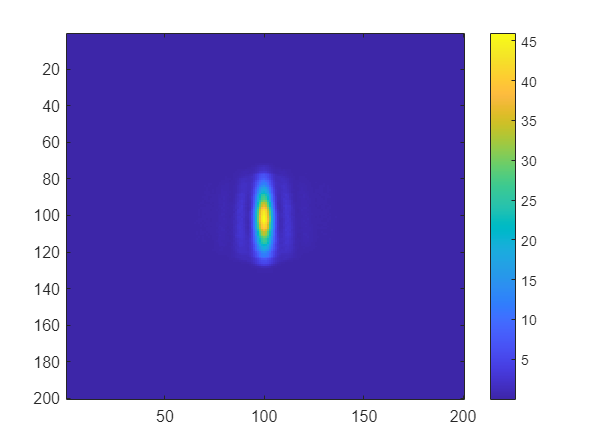

for m = 1:200
     for n = 1:200
         A = zeros(32,101);
        for i = 1:32
            %calculate distance from each point
            distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(m))^2+(map_length(n)-100)^2);
            timeshift = distance_map*dx/c;

            
            %apply the time delay to the sensor data
            step(i) = floor(timeshift(i)/4e-8);
            sensor_data_test(i,:) = sensor_data(i,:);
            sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
            sensor_timewindow(i,:) = sensor_data_new(i,26:126);
            A(i,:) = distance_map(i)*sensor_timewindow(i,:);
        end
        %sum 32 sensor data together
        
        sum_A = sum(A);
        intensity = coeff * sum_A;

        %integral'
        intensity_2 = intensity.^2;
        Q = trapz(intensity_2);
        coeff2 = 1/(4*pi*1500);
        energymap(n,m)= Q*coeff2;
     end
end

figure

%imshow(energymap/256)

%imshow(uint8(energymap))
imagesc(energymap);
colorbar;  % colorbar 的作用是生成一个代表颜色值的条状图例

toc

历时 13.093728 秒。


rea = im2uint8(mat2gray(energymap));
figure
imshow(rea)

% step
% timeshift
% distance_map
% for m = 1:200
%     for n = 1:200
%         i
%         for i = 1:32
%             %calculate distance from each point
%             distance_map(1,i)=sqrt((sensorpoistion(i)-map_width(n))^2+(map_length(m)-100)^2);
%             timeshift = distance_map*dx/c;
% 
%             
%             %apply the time delay to the sensor data
% %             step(i) = floor(tj(i)/4e-8);
% %             sensor_data_test(i,:) = sensor_data(i,:);
% %             sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));

%         end
%     end
% end

%source strength = 4pi/N*sum(distance*signal)

coeff = 4/32*pi
%distance_total = sum(distance, 'all')


%Shift test
%1st calculate how much time step to move
% step = tj(1)/4e-8%how many step to move
% step = floor(step)
% sensor_data_test = sensor_data(1,:)
% sensor_data_new = circshift(sensor_data_test, -step)

%shift test2
% function [AfterArray] = ArrayDisplacement(BeforeArray,direction,len,type)
% ArrayEnd = length(BeforeArray);
% eforeArrayL = BeforeArray(1:len);
% BeforeArrayR = BeforeArray(len+1:ArrayEnd);
% BeforeArrayL = fliplr(BeforeArrayL);
% BeforeArrayR = fliplr(BeforeArrayR);
% BeforeArray = [BeforeArrayL BeforeArrayR];
% AfterArray = fliplr(BeforeArray);

%apply the time delay to the sensor data
step = zeros(1,32)
sensor_data_test = zeros(32,1251);
sensor_data_new = zeros(32,1251);
tj = distance*dx/c;
for i = 1:32
    step(i) = floor(tj(i)/4e-8);
    sensor_data_test(i,:) = sensor_data(i,:);
    sensor_data_new(i,:) = circshift(sensor_data_test(i,:), -step(i));
    %plot the shifted data 
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, sensor_data_new(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
    %axis([0,10.5,-inf,inf]);
end

%ATP extract time window
% source_signal = source_mag * sin(2 * pi * source_freq * t_array_new);
% figure
% plot(t_array_new * scale, source_signal, 'r-');
% xlabel(['Time [' prefix 's]']);
% ylabel('Source strength');
% tend = 5.2e-6;
% tstart = 1e-6;

%timewindow = t_array_new(26:126)

sensor_timewindow = sensor_data_new(:,26:126)
figure
stackedPlot(timewindow, sensor_timewindow);
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');

figure

stackedPlot(Kgrid.t_array,sensor_data)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');

figure
stackedPlot(Kgrid.t_array,sensor_data_new)
ylabel('Sensor');
xlabel(['Time [' prefix 's]']);
title('Sensor Pressure Signal');


%calculate intensity
figure
A = zeros(32,1251)
A(1,:) = distance(1)*sensor_data_new(1,:);
for i = 1:32
    A(i,:) = distance(i)*sensor_data_new(i,:);
    subplot(32, 1, i);
    plot(Kgrid.t_array * scale, A(i,:), 'r-');
    set(gca,'XTick',[],'YTick',[]);
end
figure
sum_A = sum(A)

%plot(Kgrid.t_array * scale, sum_A, 'r-');
intensity = coeff * sum_A
plot(Kgrid.t_array * scale, intensity, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Source strength');


%integral'
intensity_2 = intensity.^2;
Q = trapz(intensity_2)
coeff2 = 1/(4*pi*1500)
%fun = @(x) exp(-x.^2).*log(x).^2;
fun = @(x) (coeff2*sum(A)).^2
%fun_2 = fun.^2
q = integral(fun,0,5e-05,'ArrayValued',true)
figure
plot(Kgrid.t_array * scale, q, 'r-');
xlabel(['Time [' prefix 's]']);
ylabel('Energy');



%original received signal
step(1)
%sensor_data_new(1,:) = circshift(sensor_data_test(1,:), -step);
figure
subplot(2,1,1);
plot(Kgrid.t_array * scale, sensor_data_test(1,:), 'r-');
set(gca,'XTick',[],'YTick',[]);
xlabel(['Time [' prefix 's]']);
%shifted signal
subplot(2,1,2);
plot(Kgrid.t_array * scale, sensor_data_new(1,:), 'r-');
xlabel(['Time [' prefix 's]']);

% sensor_data_new = distance * sensor_data
% figure
% subplot(2,1,1);
% plot(Kgrid.t_array * scale, sensor_data_new, 'r-');
% subplot(2,1,2);
% plot(Kgrid.t_array * scale, sensor_data(31,:), 'r-');



help kWaveGrid

